**Pregunta 2**

Se verifica el controlador propuesto.

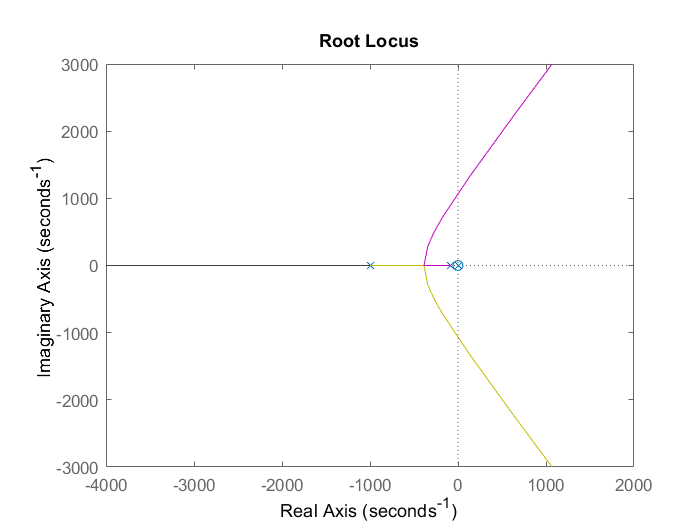

close all
clear all
clc


% Config:
s = tf('s');

optionss=bodeoptions;
optionss.MagVisible='on';
optionss.PhaseMatching='on';
optionss.PhaseMatchingValue=-180;
optionss.PhaseMatchingFreq=1;
optionss.Grid='on';

Planta = 1/((s+80)*s*s);
C_propuesto = ((s+1)^4)/(s*s*(s+1000)*(s+1000));
rlocus(Planta*C_propuesto);

Si se hace zoom, se observa que con el controlador propuesto es posible estabilizar el lazo. 

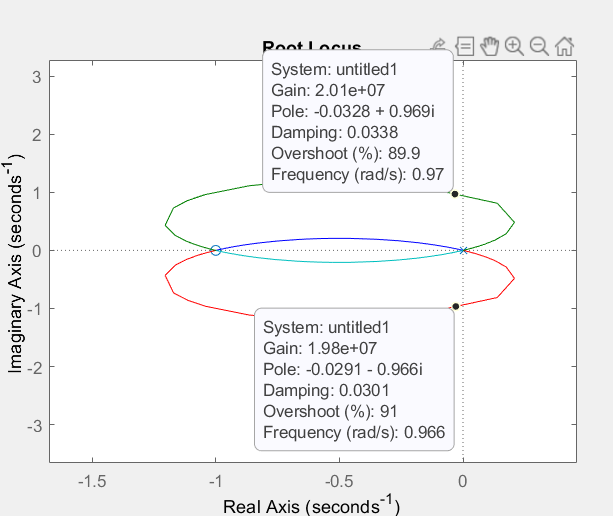

Sin embargo, luego de haber hecho un análisis exhaustivo, se decide quitar un cero y un polo del control propuesto debido a que no eran necesarios, y es mejor tener un controlador un poco más simple.

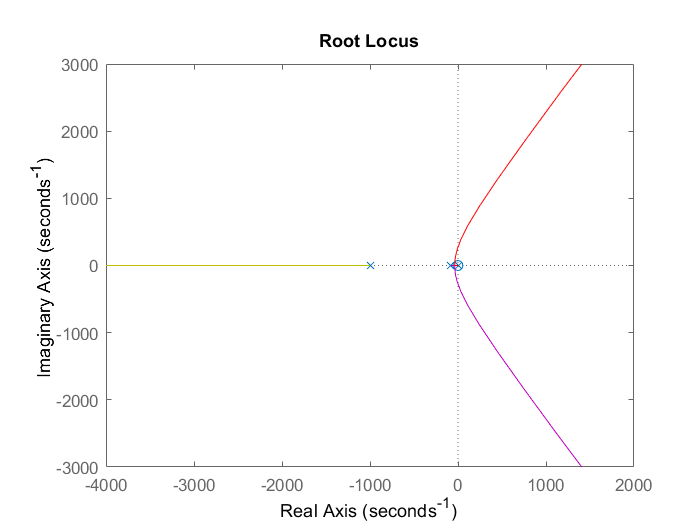

C_propuesto_2 = ((s+1)^3)/(s*s*(s+1000));
rlocus(C_propuesto_2*Planta);

Una vez mas, al hacer zoom, se verifica que es posible estabilizar el lazo:

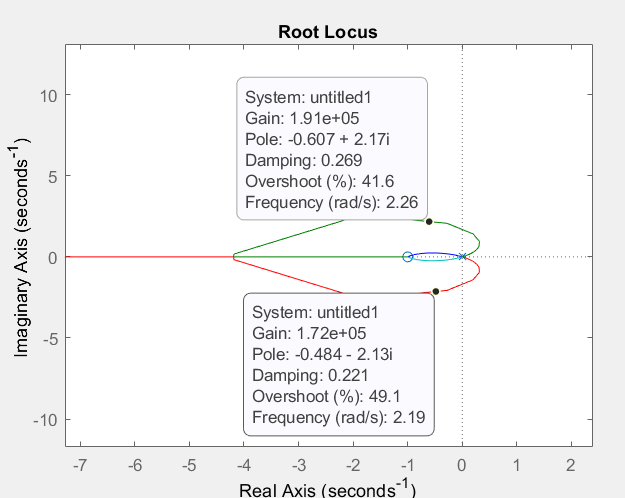

Ahora, se observa el diagrama de Bode para determinar la ganancia necesaria para garantizar que sea de 60° MF.

% figure();
% bode(C_propuesto_2*Planta, optionss)

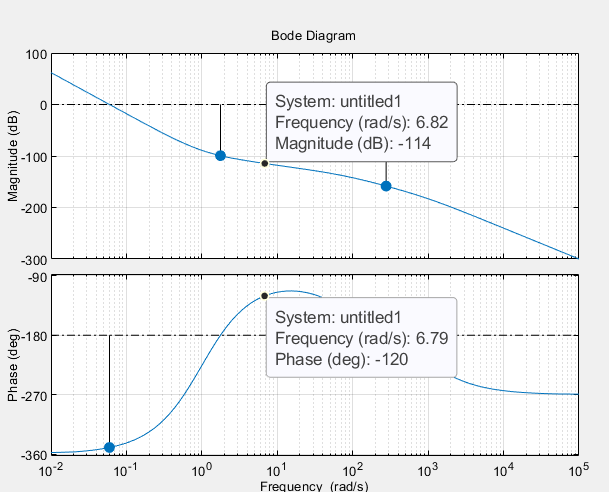

Se observa que con una ganancia de k=114db se puede lograr 60° MF. Pero, al probar con esa magnitud, verifico que me falta un poco más para ese MF. Por ende, elijo un k=115db.

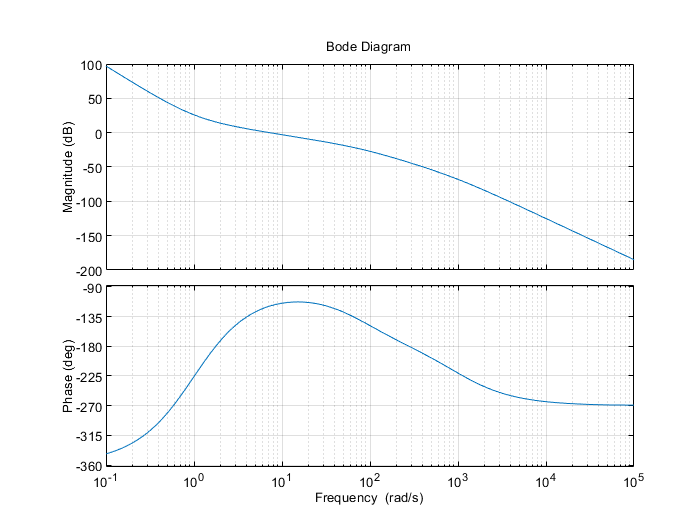

k_aux = db2mag(115);
C_final = C_propuesto_2*k_aux;
% figure();
% bode(C_final*Planta, optionss);

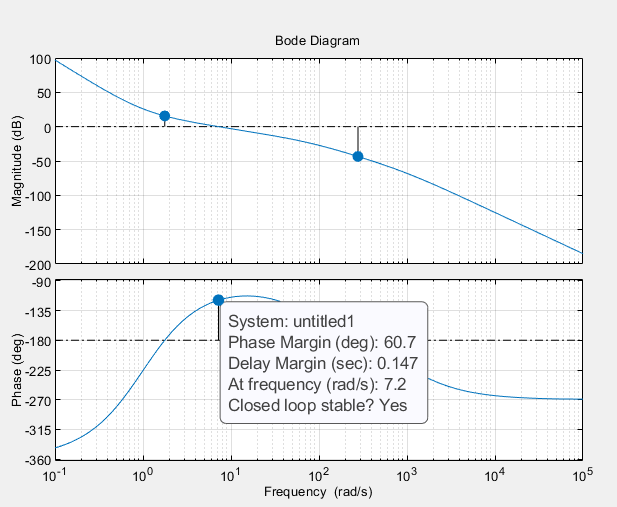

Ahora sí puedo confirmar que para esa ganancia obtengo un margen de fase de 60°

Para calcular el Ts, realizo iteraciones tal de encontrar el Ts que no me reste mas de 5 grados de margen de fase.

% 
% %calculo de Ts
% T = [0.1 0.22 0.01 0.0075 0.05 0.04 0.03 0.02 0.001];
% 
% 
% figure()
% bode(C_final*Planta, optionss, 'black');
% grid on
% hold on
% for i=1:length(T)
%     T(i)
%     Pad=(1-T(i)/4*s)/(1+T(i)/4*s);
%     bode(C_final*Planta*Pad, optionss)
% end
% 
% legend('L', '0.1', '0.22',' 0.01 ', '0.0075','0.05 ','0.04 ','0.03 ','0.02 ','0.001')
% hold off

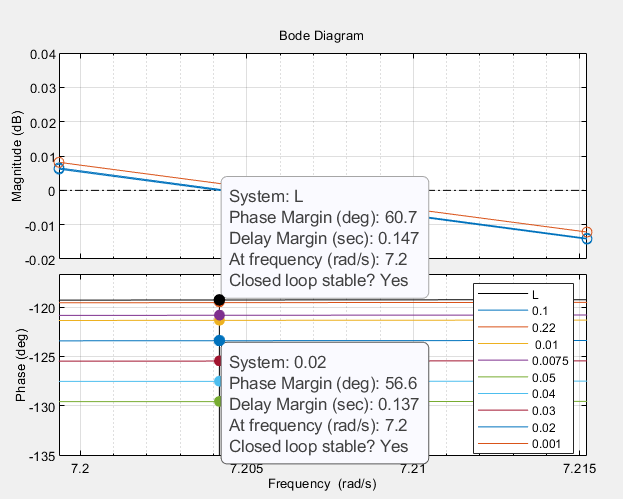

En el diagrama de arriba, se observa que con un Ts = 0.02 me garantizo que me resta 5°MF.

pade = (1-0.02/4*s)/(1+0.02/4*s);
L = C_final*Planta*pade;
% bode(L, optionss)

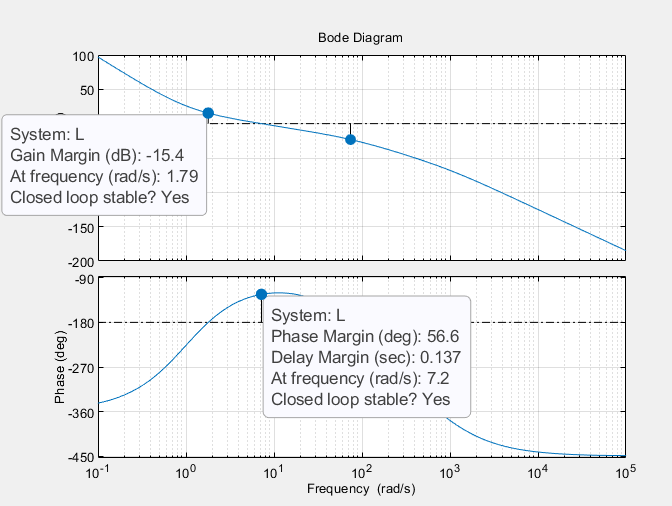

Se observan los márgenes de fase y de ganancia del diseño empleado.

%Para el Simulink
C_d = c2d(C_final,0.1,'tustin');

Ahora, se grafican las *transferencias de interés*.

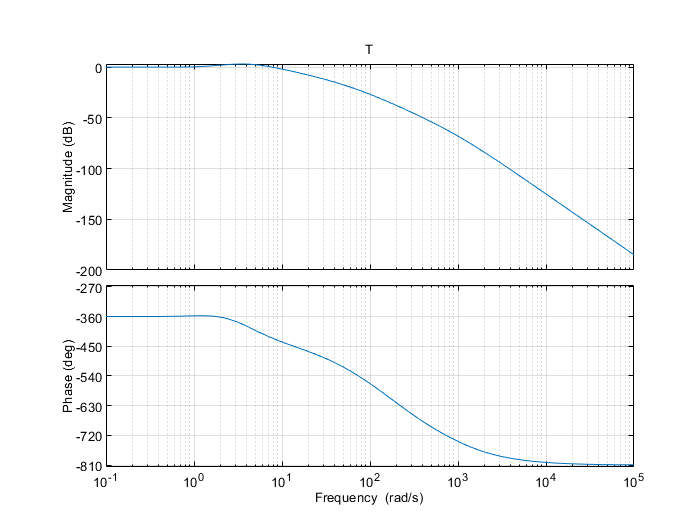

% %grupo de las 4
T_transf = minreal(L/(1+L)); 
figure() 
bode(T_transf,optionss);title('T');

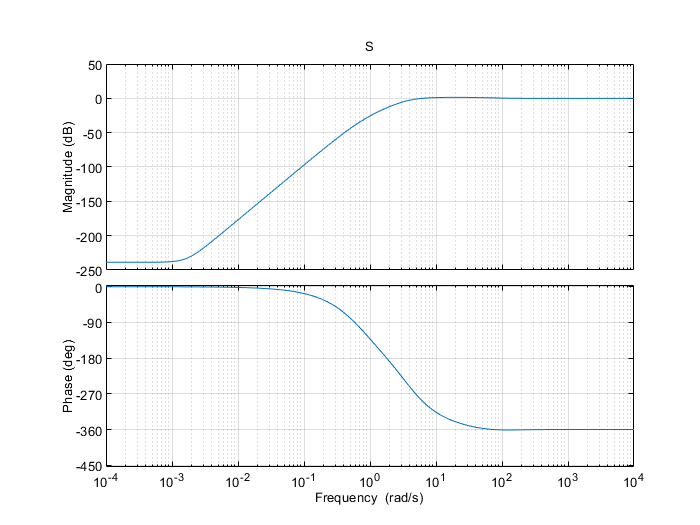

S_transf = 1 - T_transf;  
figure()
bode(S_transf,optionss);title('S');

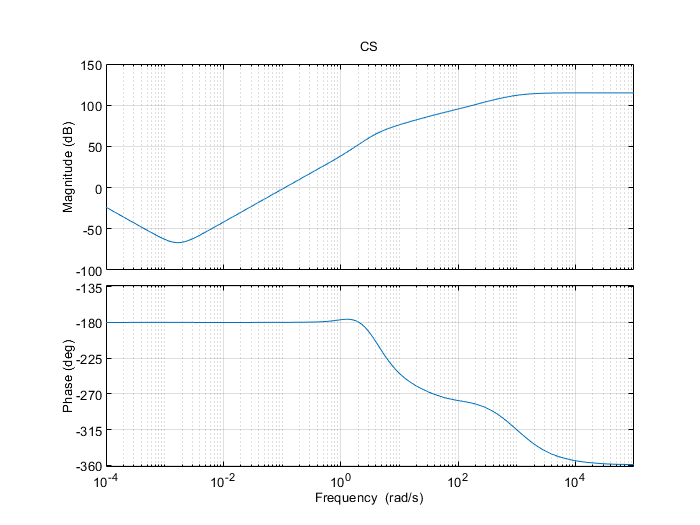

CS = minreal(C_final*S_transf); 
figure()
bode(CS,optionss);title('CS');

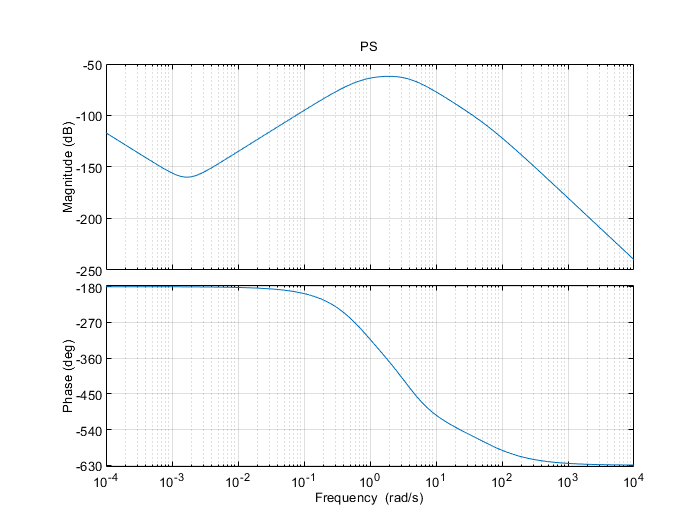

PS = minreal(Planta*S_transf);
figure()
bode(PS,optionss);title('PS');

Ahora grafico la respuesta al escalón:

*Respuesta al escalón*

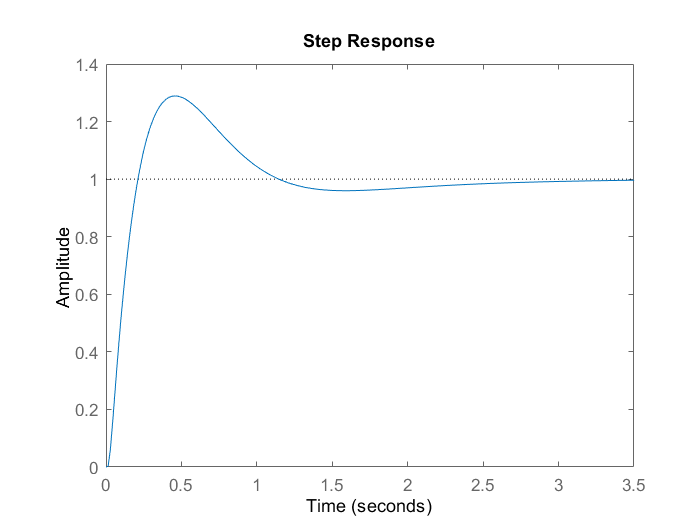

figure()
step(T_transf);

Se observa que  la respuesta se estabiliza bastante rápido.

*Margen de estabilidad*

Para calcular el márgen de estabilidad, basta con graficar el diagrama de bode de S (que se puede ver más arriba) y observar su valor máximo en el diagrama de magnitud. 

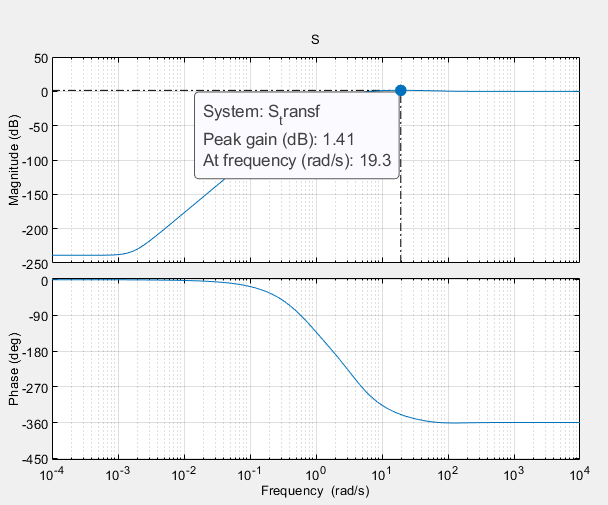

Se nota que el valor máximo es de 4.71dB. El margen de estabilidad se calcula como 1/sobrepico.

s_m = 1/db2mag(1.41)

s_m = 0.8502

Esto da como resultado un margen de estabilidad s_m = 0.8502